t_final = 0.3

t_final = 0.3000

t = 0:0.002:t_final;
y_ref = ones(1,size(t,2));
theta_ref_sim = 20; 

mot = 0;

sub = mot+1;
% PID0
Kp0 = -21.6;
Kd0 = -0.423;
% PID1
Kp1 = -21.4;
Kd1 = -0.43;

Kp = [Kp0 Kp1];
Kd = [Kd0 Kd1];
mu = [-1.4479 -1.4684];
tau = [0.0401 0.0409];

figure
plot(t,y_ref,":")
hold on
xlim([0 t_final])
title("Normalized step Response (PD)")
ylabel("normalized position")
xlabel("time (s)")


C = pid(Kp(sub),0,Kd(sub));


G = tf([mu(sub)],[tau(sub) 1 0]);

L = C*G;
Ld = c2d(L,1/500);

T_pd = feedback(Ld,1);

[y_sim,tOut] = step(T_pd);
stepinfo(T_pd)

ans = struct with fields:
         RiseTime: 0.0640
    TransientTime: 0.1920
     SettlingTime: 0.1920
      SettlingMin: 0.9121
      SettlingMax: 1.0533
        Overshoot: 5.3277
       Undershoot: 0
             Peak: 1.0533
         PeakTime: 0.1300


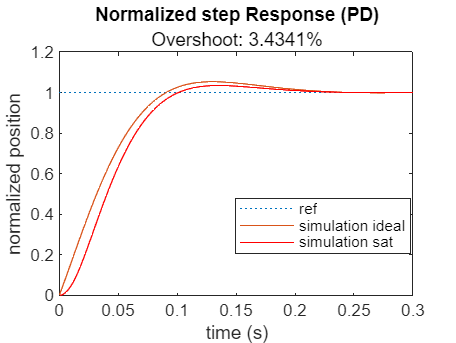

plot(tOut,y_sim)


% PID0 + sat
pidq = "lab4/pidq";
h = load_system(pidq);
simIn = Simulink.SimulationInput(pidq);
simIn= setVariable(simIn,"setP",theta_ref_sim);
simIn= setVariable(simIn,"Kp",Kp(sub));
simIn= setVariable(simIn,"Kd",Kd(sub));
simIn= setVariable(simIn,"dcg",mu(sub));
simIn= setVariable(simIn,"tau",tau(sub));
out = sim(simIn,"UseFastRestart","on");

% out = sim("lab3/pidq");

t_sim_sat = out.yout{1}.Values.Time;
y_sim_sat = out.yout{1}.Values.Data;
y_sim_sat_norm = y_sim_sat/theta_ref_sim;
overshoot = 100*(max(y_sim_sat_norm)-1);

plot(t_sim_sat,y_sim_sat_norm,"r");
subtitle("Overshoot: " +overshoot + "%")


hold off

legend(["ref","simulation ideal","simulation sat"], "Position", [0.5565 0.2654 0.3041, 0.1544])

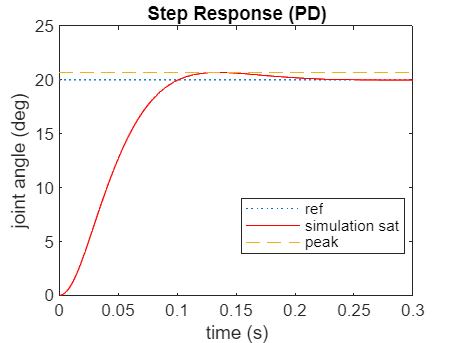

theta_ref = theta_ref_sim*ones(1,size(t,2));
theta_peak = max(y_sim_sat);

figure

plot(t,theta_ref,":")
hold on
plot(t_sim_sat,y_sim_sat,"r");
plot([0 t_final],[theta_peak theta_peak],"--")
xlim([0 t_final])
title("Step Response (PD)")
ylabel("joint angle (deg)")
xlabel("time (s)")
legend(["ref","simulation sat","peak"], "Position", [0.5565 0.2654 0.3041, 0.1544])

hold off